## 一、

close all;     
fclose('all'); 
clear;         
clc; 

function plot_fft(t,f)
N=10000;
fs=1/(t(2)-t(1));

F1=fft(f,N);
F1_shift=fftshift(F1);
f_axis=(-N/2:N/2-1)*(fs/N);

figure;
subplot(4,1,1);
plot(t,f,"r");
xlabel('Time (s)');
ylabel('f(t)');
title('时域波形');
grid on;

subplot(4,1,2);
plot((0:(N-1))*(fs/N),abs(F1)/N,"r");
xlabel('Frequency (Hz)'); 
ylabel('|F(\omega)|');
title('正频率的幅度谱');
grid on;

subplot(4,1,3);
plot(f_axis,abs(F1_shift/N),"r");
xlabel('Frequency (Hz)'); 
ylabel('|F(\omega)|');
title('正负频率的幅度谱');
grid on;

subplot(4,1,4);
plot(f_axis,angle(F1_shift),"r");
xlabel('Frequency (Hz)'); 
ylabel('Phase (rad)');
title('相位谱');
grid on;
end

### (1)

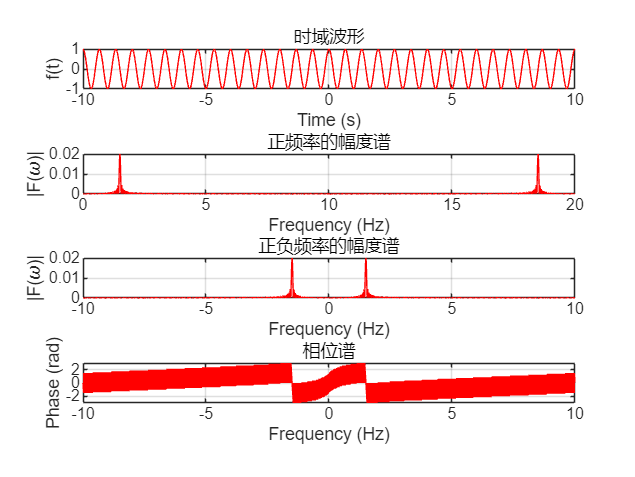

t1_1=-10:0.05:10;
f1_1=cos(3*pi*t1_1);
plot_fft(t1_1,f1_1);

### (2)

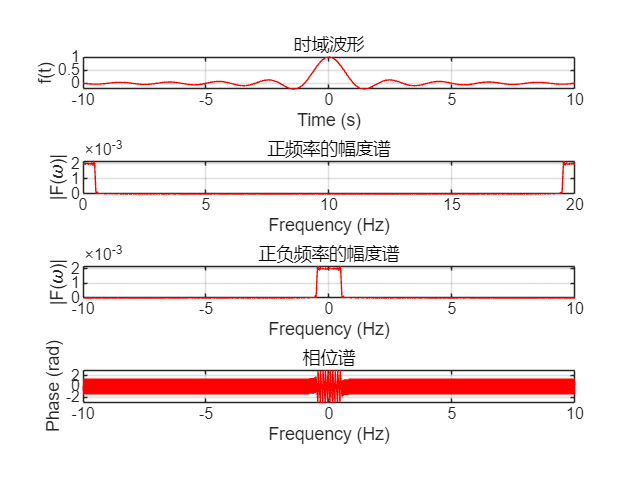

t1_2=-10:0.05:10;
f1_2=sinc(t1_2);
plot_fft(t1_2,f1_2);

### (3)

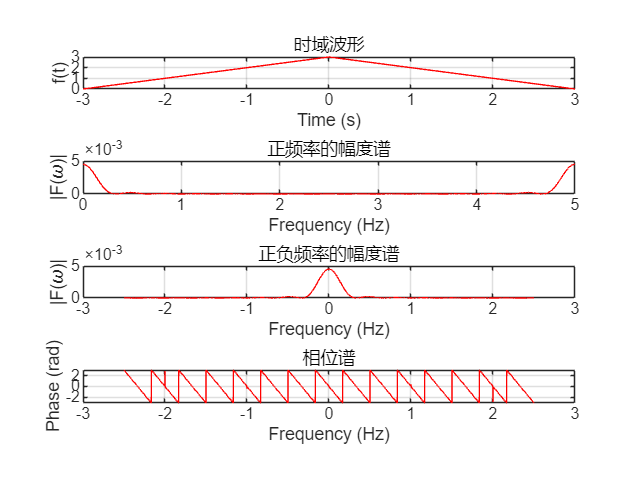

t1_3=-3:0.2:3;
f1_3=zeros(size(t1_3));
for k=1:length(t1_3)
    if t1_3(k)>=-3&t1_3(k)<=0
        f1_3(k)=t1_3(k)+3;
    else
        f1_3(k)=-t1_3(k)+3;
    end
end
plot_fft(t1_3,f1_3);

## 二、

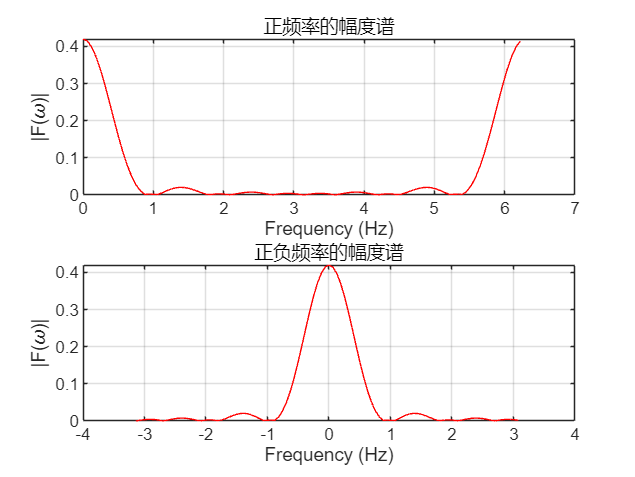

close all;     
fclose('all'); 
clear;         
clc; 

x=[1,2,3,4,5,6,6,5,4,3,2,1];
N=100;

F1=fft(x,N);
F1_shift=fftshift(F1);
f_axis=2*pi/100*(-N/2:(N/2-1));

figure;
subplot(2,1,1);
plot(2*pi/100*(0:(N-1)),abs(F1)/N,"r");
xlabel('Frequency (Hz)'); 
ylabel('|F(\omega)|');
title('正频率的幅度谱');
grid on;

subplot(2,1,2);
plot(f_axis,abs(F1_shift/N),"r");
xlabel('Frequency (Hz)'); 
ylabel('|F(\omega)|');
title('正负频率的幅度谱');
grid on;

## 三、

### (1)

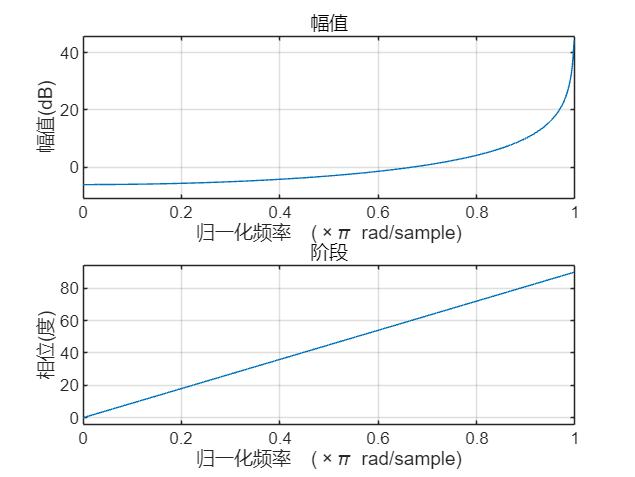

num=[1,0];
den=[1,1];
figure;
freqz(num,den);

### (2)

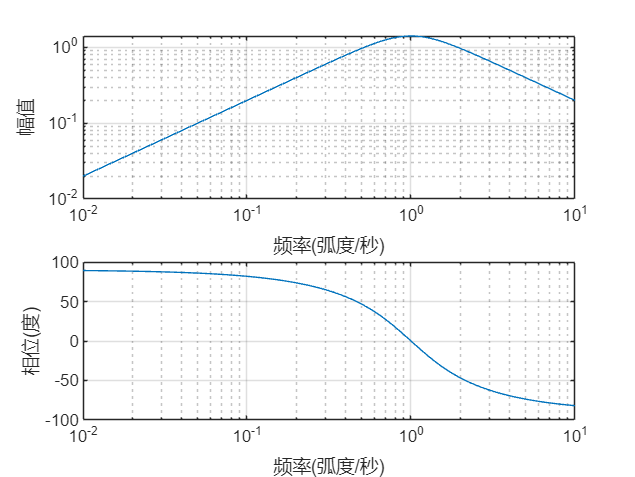

num=[0,2,0];
den=[1,sqrt(2),1];
figure;
freqs(num,den);

### (3)

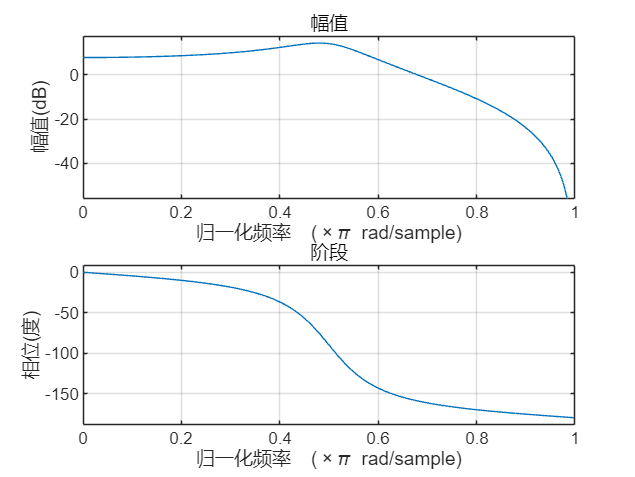

num=[1,2,1];
den=[1,0,0.61];
figure;
freqz(num,den);

### (4）

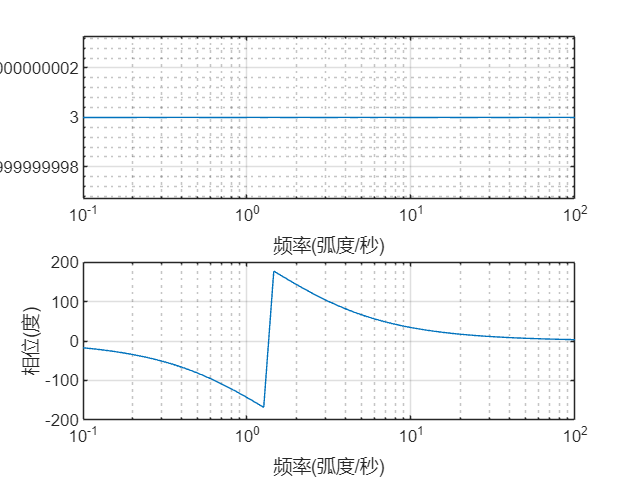

num=3*conv([1 -1],[1 -2]);
den=conv([1 1],[1 2]);
w=logspace(-1,2);
figure;
freqs(num,den,w);

## 四、

### 1.

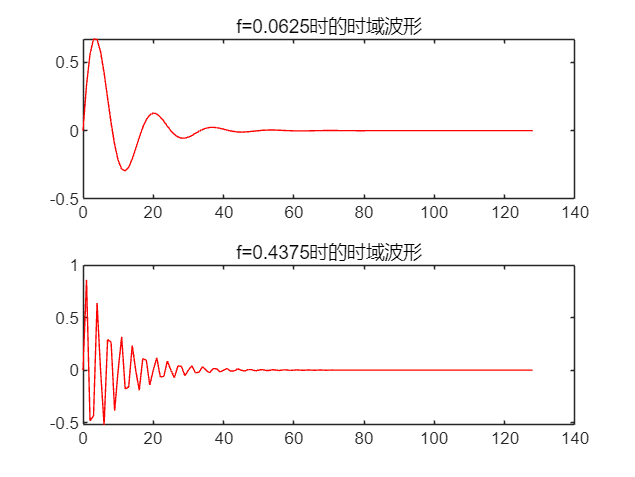

f1=0.06;
f2=0.3;
n=0:128;
a=0.1;

x1=exp(-a*n).*sin(2*pi*f1*n);
x2=exp(-a*n).*sin(2*pi*f2*n);

figure;
subplot(2,1,1);
plot(n,x1,'r');
title(['f=0.06时的时域波形']);
subplot(2,1,2);
plot(n,x2,'r');
title(['f=0.3时的时域波形']);

### 2.

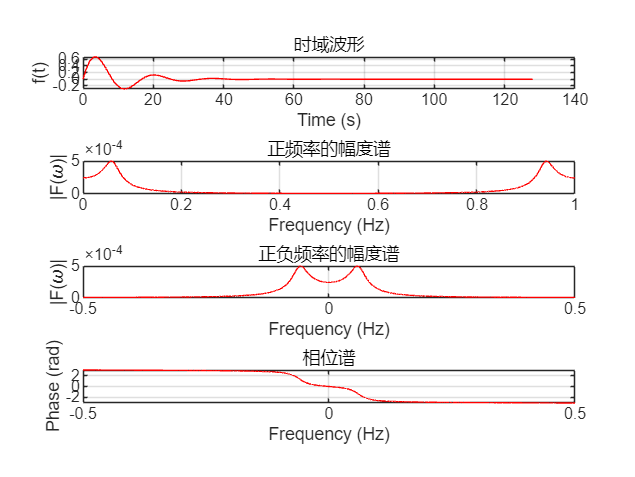

plot_fft(n,x1);

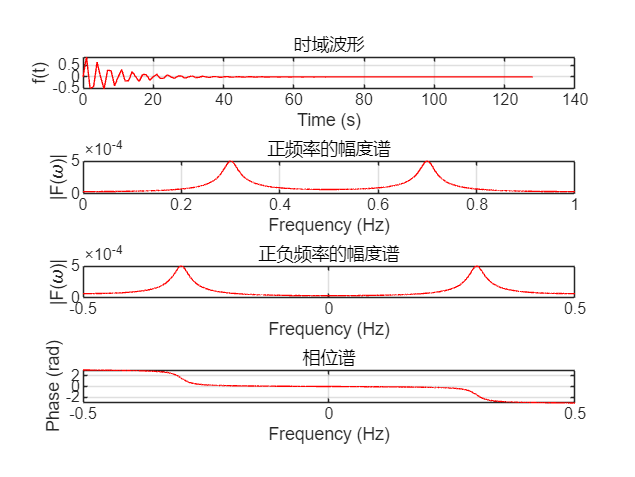

plot_fft(n,x2);

% 1.信号频率f=0.06时的频谱：
% 当f较低时，信号的频率接近零，这意味着在时域上，信号的波动较慢。频谱中，这样的低频信号将集中在靠近频率轴的低频部分，幅度在频谱的中心位置出现一个较高的峰值。
% 2.信号频率f=0.3时的频谱：
% 当f较高时，信号的频率接近0.5，即接近采样率的一半。频谱中，这种较高频率的信号会出现在接近1/2位置的地方，通常会出现对称峰值。
% 频谱差异及原因：
% 1.频率位置的差异：
% 两种情况下，信号的主频率不同，导致在频谱图上主峰的位置也不f=0.06的信号频率较低，频谱的能量集中在低频部分。f=0.3的信号频率较高，频谱的能量则集中在高频部分。
% 2.衰减效应的影响：
% 由于信号带有指数衰减项 ，衰减导致了信号的能量逐渐减少，表现为频谱上的宽度加宽、主频的峰值下降。这种效应在频率较高时可能更加明显，因为高频信号的能量分布较低。
% 3.频谱泄露：
% 如果频率f的取值不与采样率的整数倍完全对齐，可能会导致频谱泄露，使得能量扩展到附近的频率。f=0.3时，频率接近0.5，更容易出现频谱泄露的现象，这可能会导致频谱图看起来较为宽泛，主频峰值不如f=0.06时那么明显。
